# Característiques locals II

## Aparellar abecedari II

BW = rgb2gray(imread("Abecedari.png")) < 200;
imshow(BW);
BWU = BW;
BWU(end/2:end,:) = 0;

BWD = BW;
BWD(1:end/2,:) = 0;

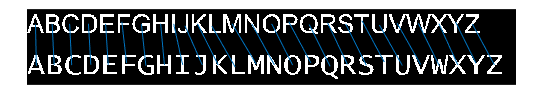

%imshow(BWU);
%imshow(BWD);
CCU = bwconncomp(BWU);
CCD = bwconncomp(BWD);

propsU = regionprops('table', CCU, 'Centroid');
propsD = regionprops('table', CCD, 'Centroid');
NumObj = CCU.NumObjects;

FU = extractHOGFeatures(BWU,propsU.Centroid,"CellSize",[16,16], "BlockSize", [3,3]);
FD = extractHOGFeatures(BWD,propsD.Centroid,"CellSize",[16,16], "BlockSize", [3,3]);

A = zeros(NumObj,NumObj);
for i = 1:NumObj
    for j = 1:NumObj
        A(j,i) = norm(FU(i,:) - FD(j,:));
    end
end

costUnmatched = max(A,[],'all');
Assig = matchpairs(A,costUnmatched);

% dibuixar emparallement
hold on
for i=1:NumObj
    line([propsU.Centroid(i,1) propsD.Centroid(Assig(i),1)],[propsU.Centroid(i,2) propsD.Centroid(Assig(i),2)]);
end
hold off

## Keypoints de Harris

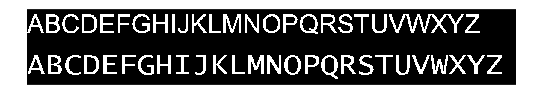

BW = rgb2gray(imread("Abecedari.png")) < 200;
imshow(BW);

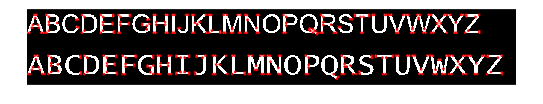

keyPoints = harris(BW,[5,5]);
keyPoints2 = harris(BW,[10,10]);
keyPoints3 = harris(BW,[15,15]);
keyPoints4 = harris(BW,[3,3]);
imshow(BW);

hold on
for i = 1:size(keyPoints,1)
    rectangle('Position',[keyPoints.Centroid(i,1)-2.5, keyPoints.Centroid(i,2)-2.5, 5, 5],'EdgeColor','r');
end
hold off

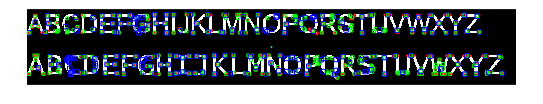


imshow(BW);

hold on
for i = 1:size(keyPoints,1)
    rectangle('Position',[keyPoints.Centroid(i,1)-2.5, keyPoints.Centroid(i,2)-2.5, 5, 5],'EdgeColor','r');
end
for i = 1:size(keyPoints2,1)
    rectangle('Position',[keyPoints2.Centroid(i,1)-5, keyPoints2.Centroid(i,2)-5, 10, 10],'EdgeColor','g');
end
for i = 1:size(keyPoints3,1)
    rectangle('Position',[keyPoints3.Centroid(i,1)-7.5, keyPoints3.Centroid(i,2)-7.5, 15, 15],'EdgeColor','b');
end
for i = 1:size(keyPoints4,1)
    rectangle('Position',[keyPoints4.Centroid(i,1)-1.5, keyPoints4.Centroid(i,2)-1.5, 3, 3],'EdgeColor','g');
end
hold off

A mesura que augmentem la mida de la finestra podem observar dues diferències. En el cas que dues cantonades estan molt pròximes entre elles, la finestra pot englobar les dues, fent que detecti una sola cantonada. L'altra diferència és que al englobar més píxels, corvatures que abans no es detectaven com a cantonada, ara sí que es detecten ja que es produeix un canvi de gradient major.

Les mides de finestra molt petites no es detecten, ja que és més difícil que les poques caselles que composen la finestra tingui canvis de gradient.

function [kp] = harris(I, windowSize)
    hx = [1 0 -1; 2 0 -2; 1 0 -1];
    Ix = imfilter(double(I), hx);
    hy = hx';
    Iy = imfilter(double(I), hy);
    W = ones(windowSize);
    Ix2 = imfilter(Ix.*Ix, W);
    Iy2 = imfilter(Iy.*Iy, W);
    Ixy = imfilter(Ix.*Iy, W);
    R = (Ix2.*Iy2 - (Ixy.*Ixy)) - 0.05*(Ix2+Iy2).*(Ix2+Iy2);
    k = R > 3000;
    k2 = imregionalmax(k);
    kp = regionprops('table', k2, 'Centroid');
end